# Уравнение фон Берталанфи

## Модель


$$\frac{\mathrm{dV}}{\mathrm{dt}}=\alpha V^{\frac{2}{3}} -\beta \;V,\;\alpha ,\beta >0$$


alpha = 1.5;
beta = 1;

dVdt = @(V) alpha*V.^(2/3) - beta*V;

График правой части

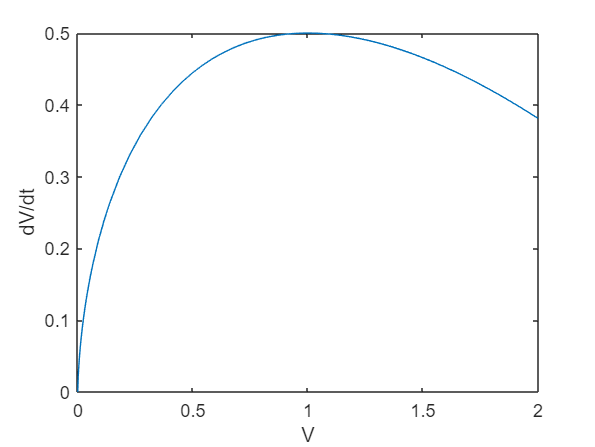

figure(1)
fplot(dVdt, [0, 2]);
xlabel('V');
ylabel('dV/dt');

## Стационарные точки


$$\lim_{\tau \to 0} \frac{V_{t+\tau \;} -V_t }{\tau }=\frac{\mathrm{dV}}{\mathrm{dt}}=0$$



$$\begin{array}{l}
\alpha V^{\frac{2}{3}} -\beta \;V=0\\
V^{\frac{2}{3}} \left(\alpha -\beta \;V^{\frac{1}{3}} \right)=0
\end{array}$$



$$V_1 =0,V_2 ={\left(\frac{\alpha }{\beta \;}\right)}^3$$


## Интегрирование уравнения (по времени)

Время интегрирования (откуда докуда)

T = 10;
tspan = [0, T];

Начальное условие (какой объем был в момент времени 0):

V0 = [.5, 1, 1.5, 2.8];

Можно начать интегрировать. Делается это с помощью функции `ode45 (Ordinary Differential Equation)`

dV_fun = @(t, V) alpha*V.^(2/3) - beta*V;
[t, V] = ode45(dV_fun, tspan, V0);
% [t, V] = ode45(@(t, V) alpha*V.^(2/3) - beta*V, tspan, V0);

Первые 5 и последние 5 строк резульатов:

[t([1:5, end-4:end]), V([1:5, end-4:end], :)]

ans =          0    0.5000    1.0000    1.5000    2.8000
    0.0565    0.5253    1.0282    1.5262    2.8101
    0.1129    0.5509    1.0564    1.5522    2.8200
    0.1694    0.5769    1.0846    1.5780    2.8297
    0.2258    0.6032    1.1128    1.6036    2.8393
    9.2258    3.1596    3.2215    3.2655    3.3469
    9.4194    3.1728    3.2310    3.2722    3.3486
    9.6129    3.1852    3.2399    3.2786    3.3503
    9.8065    3.1968    3.2482    3.2846    3.3518
   10.0000    3.2078    3.2560    3.2902    3.3532


Визуализация решения (траектории)

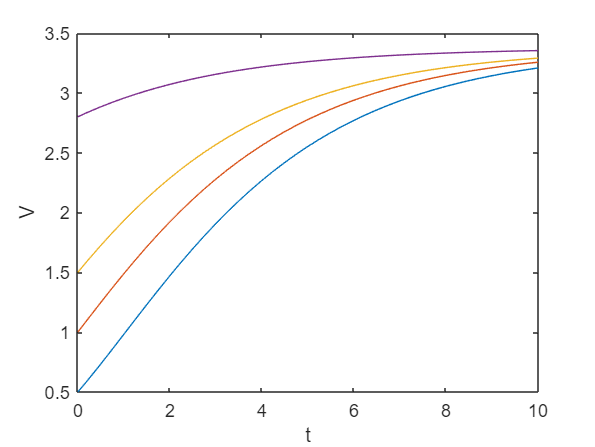

figure(2)
plot(t, V);
xlabel('t');
ylabel('V');